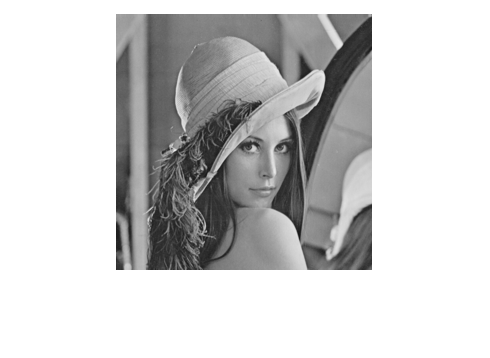

img = imread("../materials/Lena.tif");
[M, N] = size(img);
imshow(img)

tmp = zeros([M, N]);
fft_img = zeros([M, N]);
x = 0:M-1;
y = 0:N-1;
% use 1-D FFT twice to accelerate
for u = 1:M
    tmp(u, :) = sum(double(img) .* exp(-1i * 2 * pi * (u-1) * x' / M), 1);
end
for v = 1:N
    fft_img(:, v) = sum(tmp .* exp(-1i * 2 * pi * (v-1) * y / N), 2);
end

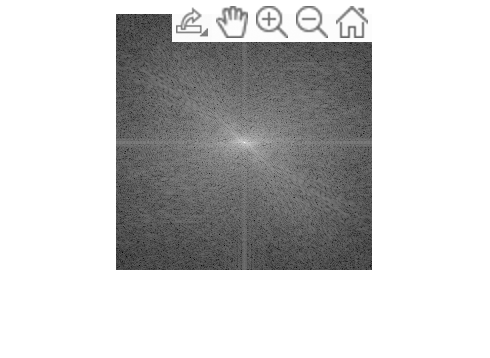

shift_fft = zeros(size(fft_img));
shift_fft(1:M/2,1:N/2) = fft_img(1+M/2:end,1+N/2:end);
shift_fft(1+M/2:end, 1+N/2:end) = fft_img(1:M/2,1:N/2);
shift_fft(1:M/2,1+N/2:end) = fft_img(1+M/2:end, 1:N/2);
shift_fft(1+M/2:end, 1:N/2) = fft_img(1:M/2,1+N/2:end);
imshow(real(log(shift_fft)),[])